# `Conditional Statements in MATLAB`

# ` - if, elseif, else`

# ` - switch, case, otherwise`

# ` - fprintf`

` - if expression, statements, end evaluates an expression, and executes a group of statements when the expression is true. An expression is true when its result is nonempty and contains only nonzero elements (logical or real numeric). Otherwise, the expression is false.`

` - The elseif and else blocks are optional. The statements execute only if previous expressions in the if...end block are false. An if block can include multiple elseif blocks.`

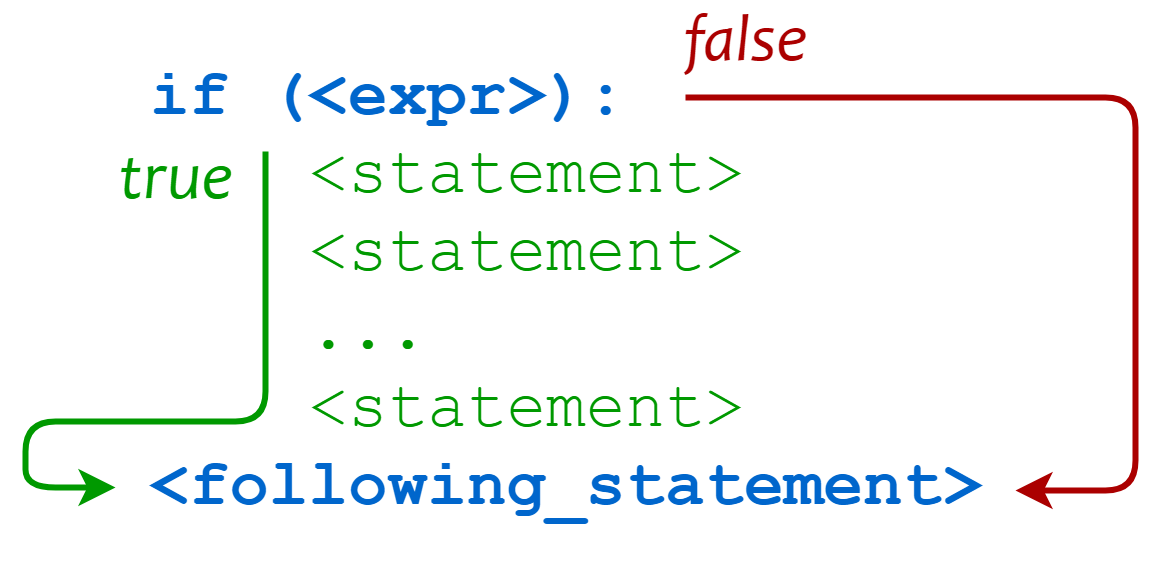

# `- if, elseif, else`

# `Ex`

a_1 = 3;
a_2 = 10;
if a_1 < a_2    %  # Truthy
    disp('yes')
end

yes


# `Ex`

a_1 = 3;
a_2 = 10;
if a_1 > a_2    %  # Falsy
    disp('yes')
else
    disp('no')
end

no


# `Ex`

x = 0;
if x ~= 0
    disp('Nonzero value')
else
    disp('zero value')
end

zero value


# `Ex`

x = 10;
minValue = 0;
maxValue = 8;

if (x >= minValue) && (x <= maxValue)
    disp('Value within specified range.')
elseif (x > maxValue)
    disp('Value exceeds maximum value.')
else
    disp('Value is below minimum value.')
end

Value exceeds maximum value.


# `Ex`

limit = 0.25;
A = rand(10,1)

A =     0.0326
    0.5612
    0.8819
    0.6692
    0.1904
    0.3689
    0.4607
    0.9816
    0.1564
    0.8555


if any(A > limit)
    disp('There is at least one value above the limit.')
else
    disp('All values are below the limit.')
end

There is at least one value above the limit.


# 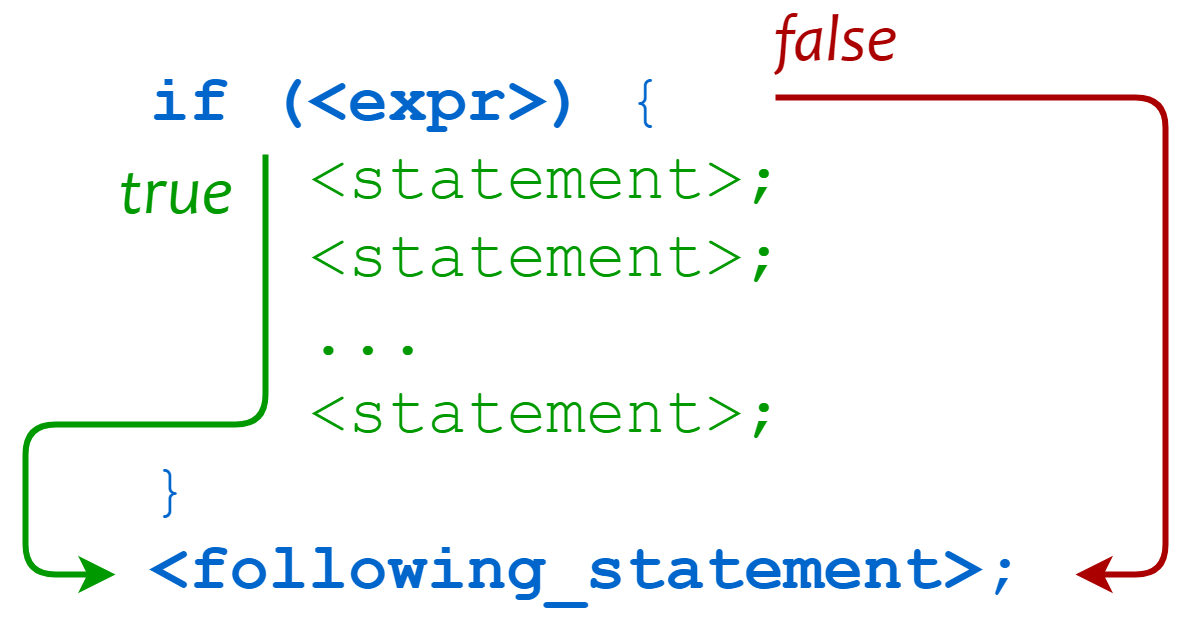

# `- switch, case, otherwise`

` - switch switch_expression, case case_expression, end evaluates an expression and chooses to execute one of several groups of statements. Each choice is a case.`

` - The switch block tests each case until one of the case expressions is true. A case is true when:`

` - For numbers, case_expression == switch_expression.`

` - For character vectors, strcmp(case_expression,switch_expression) == 1.`

` - For objects that support the eq function, case_expression == switch_expression. The output of the overloaded eq function must be either a logical value or convertible to a logical value.`

` - For a cell array case_expression, at least one of the elements of the cell array matches switch_expression, as defined above for numbers, character vectors, and objects.`

` - When a case expression is true, MATLAB® executes the corresponding statements and exits the switch block.`

` - An evaluated switch_expression must be a scalar or character vector. An evaluated case_expression must be a scalar, a character vector, or a cell array of scalars or character vectors.`

` - The otherwise block is optional. MATLAB executes the statements only when no case is true.`

# `Ex`

n = 10;

switch n
    case -1
        disp('negative one')
    case 0
        disp('zero')
    case 1
        disp('positive one')
    otherwise
        disp('other value')
end

other value


# `Ex`

result = 52;

switch(result)
   case 52
      disp('result is 52')
   case {'52', 78}
      disp('result is 52 or 78')
end

result is 52


# `Exercises`

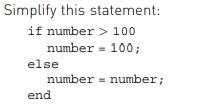

number_1 = 150;
if number_1 > 100
   number_1 = 100;
end

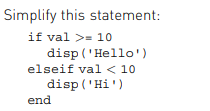

val = 8;
if val >= 10
 disp('Hello')
else
 disp('Hi')
end

Hi


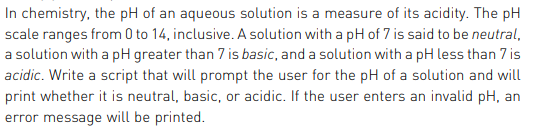

ph =  8.5;        % input('Enter the pH of the solution: ');
if ph >=0 && ph <= 14
 if ph < 7
 disp('It is acidic')
 elseif ph == 7
 disp('It is neutral')
 elseif ph > 7
 disp('It is basic')
 end
else
 disp('Error in pH!')
end

It is basic


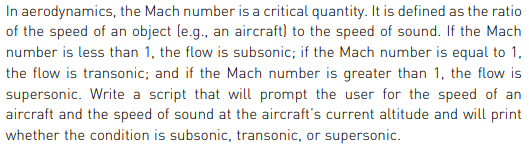

% Plane_speed 
% sound_speed 
% mach = plane_speed/sound_speed;
mach = 0.86; 
if mach < 1
 disp('Subsonic')
elseif mach == 1
 disp('Transonic')
else
 disp('Supersonic')
end

Subsonic


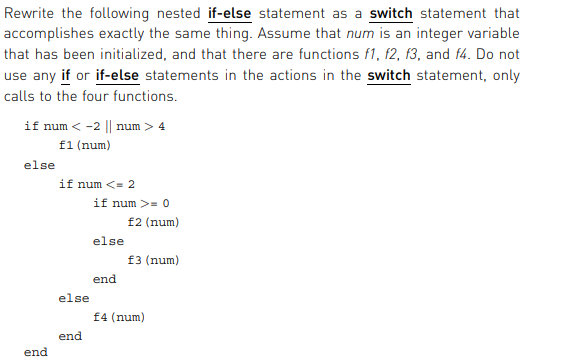

num = 3;
switch num
 case {-2, -1}
      disp('f3(num)')
 case {0, 1, 2}
      disp('f2(num)')
 case {3, 4}
     disp('f4(num)')
 otherwise
   disp('f1(num)')  
end

f4(num)


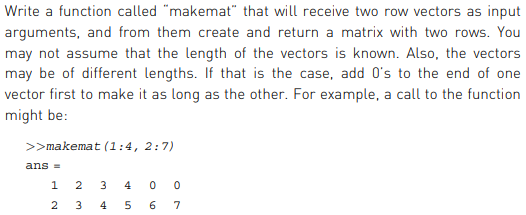

v1 = (1:4)

v1 =      1     2     3     4


v2 = (2:7)

v2 =      2     3     4     5     6     7


len1 = length(v1);
len2 = length(v2);
if len1 ~= len2
   if len1>len2
     diff = len1-len2;
     addend = zeros(1,diff);
     v2 = [v2 addend];
  else
    diff = len2-len1;
    addend = zeros(1,diff);
    v1 = [v1 addend];
   end
   [v1;v2]
end

ans =      1     2     3     4     0     0
     2     3     4     5     6     7


# 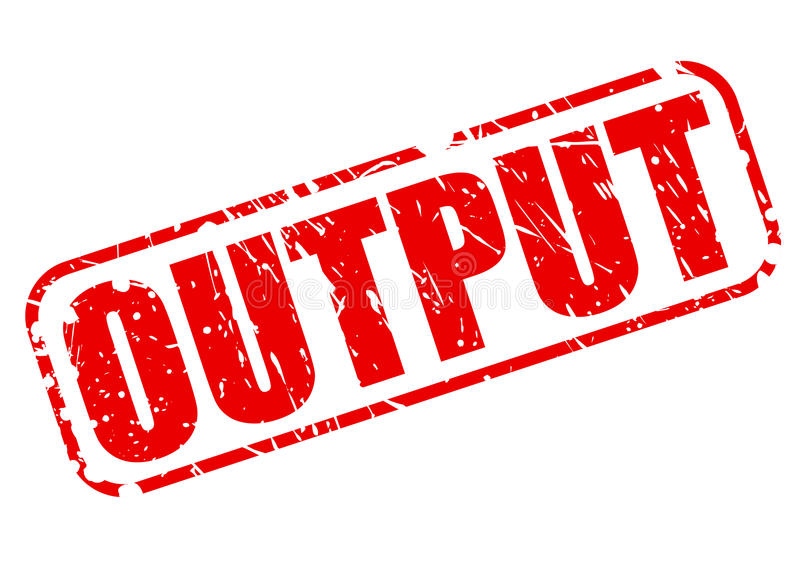

# `fprintf`

fprintf('text')

text

fprintf('text_1 \ntext_2')   %  creat a blank line

text_1 
text_2

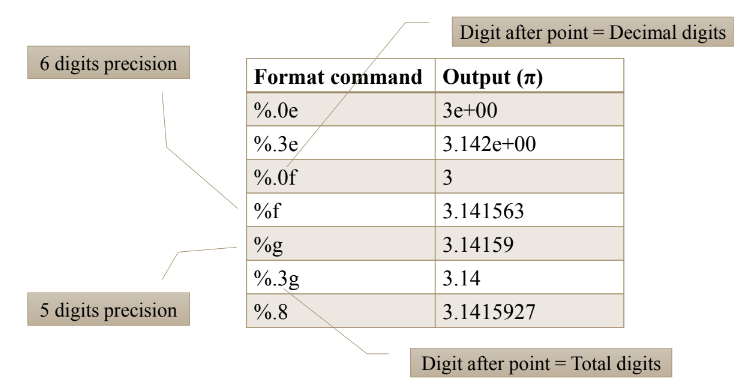

value = pi ;
fprintf('%d ', value)

3.141593e+00 

fprintf('%0.0e ', value)

3e+00 

fprintf('%0.3e ', value)

3.142e+00 

fprintf('%0.3f ', value)

3.142 

fprintf('%f ', value)

3.141593 

fprintf('%g ', value)

3.14159 

fprintf('%0.3g ', value)

3.14 

# `Ex`

list_num = 2:10 ;
fprintf('%d', list_num)

2345678910

fprintf('%d\n', list_num)

2
3
4
5
6
7
8
9
10


# `Ex`

list_num_1 = [3  8  6 ;
              5  1  7] 

list_num_1 =      3     8     6
     5     1     7


fprintf('%d\n' , list_num_1)

3
5
8
1
6
7


fprintf('%d %d %d\n', list_num_1)

3 5 8
1 6 7


fprintf('%d %d %d\n', list_num_1')

3 8 6
5 1 7


# `Ex`

x = 1:10 ;
y = sqrt(x) ;
merg_sqrt = [x; y]

merg_sqrt =     1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000
    1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623


fprintf('if the number is %g, its square root is:%0.4g\n',merg_sqrt)

if the number is 1, its square root is:1
if the number is 2, its square root is:1.414
if the number is 3, its square root is:1.732
if the number is 4, its square root is:2
if the number is 5, its square root is:2.236
if the number is 6, its square root is:2.449
if the number is 7, its square root is:2.646
if the number is 8, its square root is:2.828
if the number is 9, its square root is:3
if the number is 10, its square root is:3.162


# `Ex`